**Equilibrium and Stability Analysis of the Hock-Weil Model:**

This script analyzes the long-term behavior of the system by focusing on the dependency ratios $y$ (Youth/Workers) and $o$ (Elderly/Workers). Also, it forces the model into a "Zero Growth" state to analyze stock stability.

clear; clc; close all;

Load Parameters:

P = get_parameters();

% Recalculate target psi to ensure we are analyzing the corrected model
disp(['Analyzing stability for Fertility Preference parameter psi = ', num2str(P.psi_base)]);

Analyzing stability for Fertility Preference parameter psi = 0.02157


Define the Ratio ODE System:

We derive these from the original stock equations, derived in Hock & Weil (2012).

Define the system as an anonymous function:

**Inputs:**

- $t$ - Time

- $X$ - State Vector $\left\lbrack \begin{array}{c}
y\\
o
\end{array}\right\rbrack$

ratio_ode = @(x) get_ratio_derivatives(x, P);

Find Equilibrium Point Numerically:

We look for points where $\frac{dy}{dt}=0$ and $\frac{do}{dt}=0$.

We use $fsolve$ starting from an initial guess.

guess = [0.5; 0.3]; 
options = optimoptions('fsolve', 'Display', 'off');

[eq_point, fval] = fsolve(ratio_ode, guess, options);

y_star = eq_point(1);
o_star = eq_point(2);

% Calculate economic variables at equilibrium
tau_star = (P.alpha * y_star + P.beta * o_star) / (1 + P.alpha * y_star + P.beta * o_star);
n_star   = P.psi_base * (1 - tau_star);

fprintf('--- Equilibrium Results ---\n');

--- Equilibrium Results ---


fprintf('Steady State Youth Ratio (y*): %.4f\n', y_star);

Steady State Youth Ratio (y*): 0.3841


fprintf('Steady State Old Ratio   (o*): %.4f\n', o_star);

Steady State Old Ratio   (o*): 0.3491


fprintf('Steady State Tax Rate    (t*): %.2f%%\n', tau_star*100);

Steady State Tax Rate    (t*): 16.35%


fprintf('Steady State Fertility   (n*): %.4f\n', n_star);

Steady State Fertility   (n*): 0.0180


Stability Analysis (Eigenvalues):

We compute the Jacobian Matrix $J$ at the equilibrium point.

$J=\left\lbrack \begin{array}{cc}
\frac{{\textrm{dy}}^* }{\textrm{dy}} & \frac{{\textrm{dy}}^* }{\textrm{do}}\\
\frac{{\textrm{do}}^* }{\textrm{dy}} & \frac{{\textrm{do}}^* }{\textrm{do}}
\end{array}\right\rbrack$.

% We use a simple finite difference method to get the Jacobian numerically
delta = 1e-6;
J = zeros(2,2);
F0 = ratio_ode(eq_point);

% Perturb y
F_y = ratio_ode([y_star + delta; o_star]);
J(:,1) = (F_y - F0) / delta;

% Perturb o
F_o = ratio_ode([y_star; o_star + delta]);
J(:,2) = (F_o - F0) / delta;

disp('--- Jacobian Matrix at Equilibrium ---');

--- Jacobian Matrix at Equilibrium ---


disp(J);

   -0.0677   -0.0068
   -0.0175   -0.0637




eigenvalues = eig(J);
disp('--- Eigenvalues ---');

--- Eigenvalues ---


disp(eigenvalues);

   -0.0767
   -0.0546




if all(real(eigenvalues) < 0)
    disp('Result: The equilibrium is STABLE (Sink).');
else
    disp('Result: The equilibrium is UNSTABLE.');
end

Result: The equilibrium is STABLE (Sink).


Phase Plane Visualization:

This visualizes the "basins of attraction" and the flow vectors.

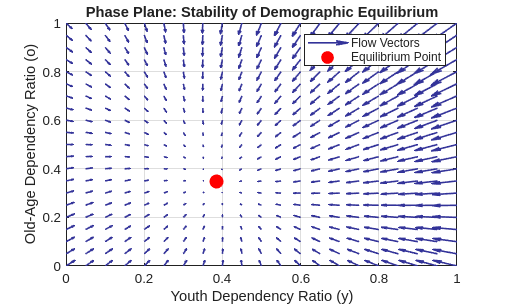

% Create a grid of (y, o) values
[Y_grid, O_grid] = meshgrid(0:0.05:1.0, 0:0.05:1.0);
dY = zeros(size(Y_grid));
dO = zeros(size(O_grid));

% Calculate vector field
for i = 1:numel(Y_grid)
    res = ratio_ode([Y_grid(i); O_grid(i)]);
    dY(i) = res(1);
    dO(i) = res(2);
end

figure('Color','w');
quiver(Y_grid, O_grid, dY, dO, 1.5, 'LineWidth', 1.2, 'Color', [0.2 0.2 0.6]);
hold on;
plot(y_star, o_star, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('Youth Dependency Ratio (y)');
ylabel('Old-Age Dependency Ratio (o)');
title('Phase Plane: Stability of Demographic Equilibrium');
legend('Flow Vectors', 'Equilibrium Point');
grid on;
axis([0 1 0 1]);

**Override parameters to represent a "Stationary" European country:**

We need $n$ (fertility) to match $\lambda_M$ (retirement rate).

target_n = P.lam_M_base;

fprintf('--- Stationary Condition ---\n');

--- Stationary Condition ---


fprintf('Retirement Rate (lambda_M): %.4f\n', P.lam_M_base);

Retirement Rate (lambda_M): 0.0222


fprintf('Target Fertility (n) needed: %.4f (approx TFR %.2f)\n', target_n, target_n*P.T_M_base);

Target Fertility (n) needed: 0.0222 (approx TFR 1.00)


Inverse Calibration:

We need to find the specific preference ($\theta$) or cost ($\xi$) that results in exactly the targeted $n$. We know: $n = \psi(1 - \tau)$.

This requires solving for equilibrium tax and $n$ simultaneously.

% Define an anonymous function that calculates the error between
% current growth rate and zero.
objective_fun = @(theta_guess) find_growth_rate(theta_guess, P);

% Solve for the "Replacement Level Theta"
options = optimset('Display','off');
theta_stationary = fzero(objective_fun, [0.01, 0.5]);

% Update Parameters with the stationary theta
P.psi_base = theta_stationary / (P.xi * (1 + theta_stationary));

fprintf('Calibrated theta for Zero Growth: %.4f\n', theta_stationary);

Calibrated theta for Zero Growth: 0.0711


disp('Running Simulation with Stationary Parameters...');

Running Simulation with Stationary Parameters...


Run Simulation:

% Initialize at stationary ratio
A_M0 = P.A_Y0 * (P.lam_Y_base / P.lam_M_base);
A_O0 = A_M0 * (P.lam_M_base / P.lam_O_base);
Y0   = [P.A_Y0; A_M0; A_O0];

[t, Y] = ode45(@(t,y) model_dynamics_stationary(t,y,P), P.tspan, Y0);

Visualization:

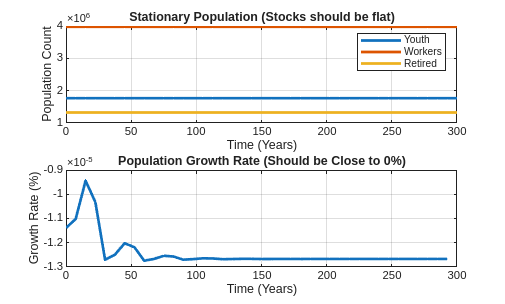

figure('Color','w');
subplot(2,1,1);
plot(t, Y, 'LineWidth', 2);
legend('Youth', 'Workers', 'Retired');
ylabel('Population Count');
xlabel('Time (Years)');
title('Stationary Population (Stocks should be flat)');
grid on;

subplot(2,1,2);

% Calculate Growth Rate over time
total_pop = sum(Y, 2);
growth_rate = diff(total_pop) ./ total_pop(1:end-1);
plot(t(1:end-1), growth_rate * 100, 'LineWidth', 2);
ylabel('Growth Rate (%)');
xlabel('Time (Years)');
title('Population Growth Rate (Should be Close to 0%)');
grid on;

**Local Functions:**

function dxdt = get_ratio_derivatives(x, P)
    y = x(1);
    o = x(2); 

Recover Parameters:

    lam_Y = P.lam_Y_base;
    lam_M = P.lam_M_base;
    lam_O = P.lam_O_base;

Economic variables:

    tau = (P.alpha * y + P.beta * o) / (1 + P.alpha * y + P.beta * o);
    n   = P.psi_base * (1 - tau);

Ratio ODEs (Derived from Stock equations):


$$\frac{dy}{dt}=\phi n-(\lambda_Y-\lambda_M)y-\lambda_Y y^2$$


$\frac{do}{dt}=\lambda_M+(\lambda_M-\lambda_O)o-\lambda_Yoy$.

    dy = P.phi * n - (lam_Y - lam_M)*y - lam_Y * y^2;
    do = lam_M + (lam_M - lam_O)*o - lam_Y * y * o;
    
    dxdt = [dy; do];
end

function err = find_growth_rate(theta, P)

Updates $\psi$ based on guess:

    xi = 2.5;
    P.psi_base = theta / (xi * (1 + theta));
    

Find equilibrium ratios for this $\theta
$:

    ratio_ode = @(x) get_ratio_derivatives(x, P);
    eq = fsolve(ratio_ode, [0.5; 0.3], optimoptions('fsolve','Display','off'));
    
    y = eq(1); o = eq(2);

Calculate $n$ at this equilibrium:

    tau = (P.alpha * y + P.beta * o) / (1 + P.alpha * y + P.beta * o);
    n   = P.psi_base * (1 - tau);

$\text{Error}=\text{Inflow}-\text{Outflow}$.

For workers, $\text{Inflow}=\lambda_Yy$, $\text{Outflow}=\lambda_M$

But the simplest check is $\phi n-\lambda_M$.

    err = (P.phi * n) - P.lam_M;
end

Simplified dynamics for this test:

function dYdt = model_dynamics_stationary(t, Y, P)
    Ay = Y(1); Am = Y(2); Ao = Y(3);
    if Am<1, Am=1; end
    y = Ay/Am; o = Ao/Am;
    tau = (P.alpha * y + P.beta * o) / (1 + P.alpha * y + P.beta * o);
    n = P.psi_base * (1 - tau);
    
    dAy = P.phi * n * Am - P.lam_Y * Ay;
    dAm = P.lam_Y * Ay - P.lam_M * Am;
    dAo = P.lam_M * Am - P.lam_O * Ao;
    dYdt = [dAy; dAm; dAo];
end